clc
close all
clearvars

load(fullfile(pwd,"data","hra","hrq_mx.mat"))
num_id = 32;

zidx = all(feat_mx==0,1);
feat_mx(:,zidx) = [];

# Histograms of HR features

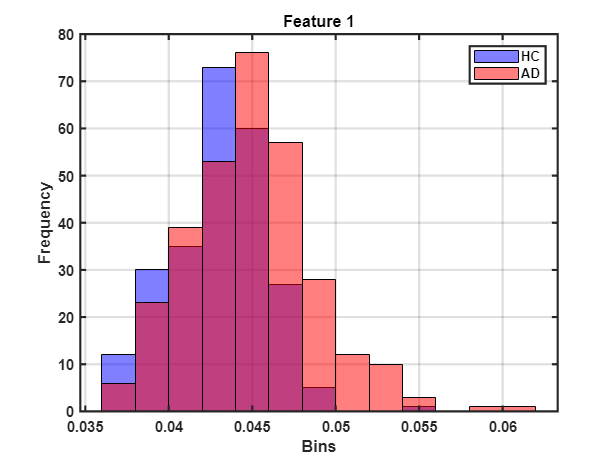

my_hist(1,feat_mx)

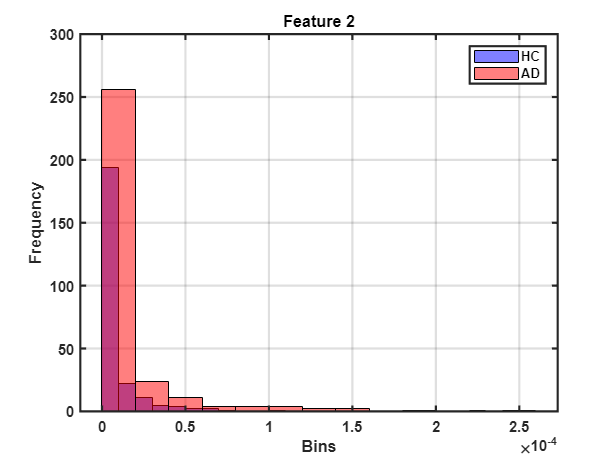

my_hist(2,feat_mx)

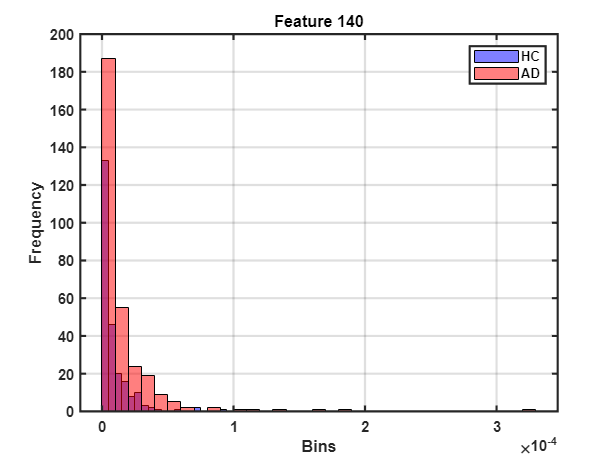

my_hist(randi(size(feat_mx,2)),feat_mx)

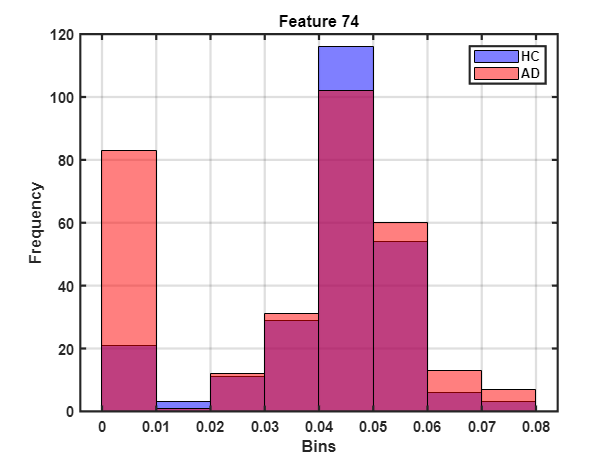

my_hist(randi(size(feat_mx,2)),feat_mx)

# Log transformation

feat_mx2 = feat_mx;
feat_mx2(feat_mx2==0) = eps;

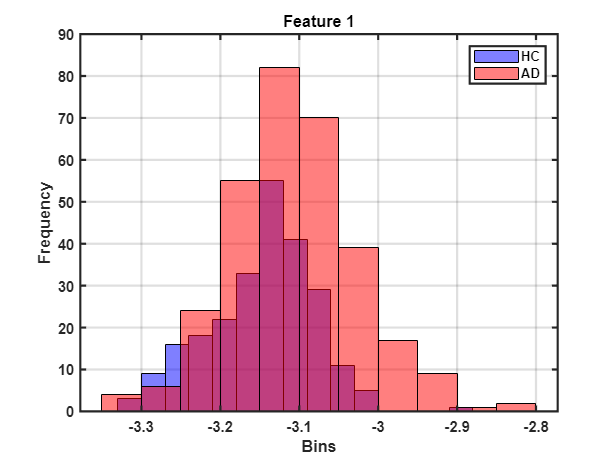

feat_mx_log = log(feat_mx2);
my_hist(1,feat_mx_log)

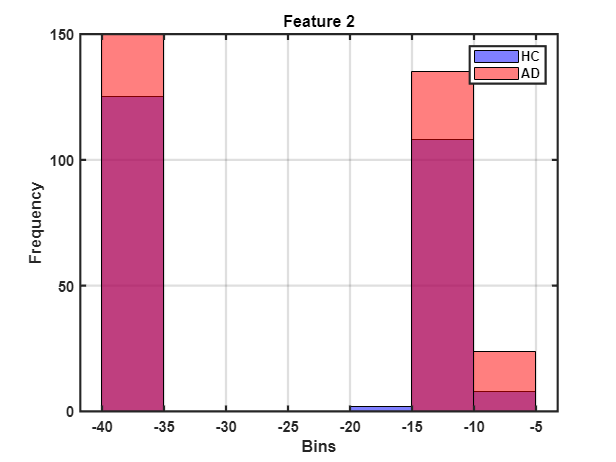

my_hist(2,feat_mx_log)

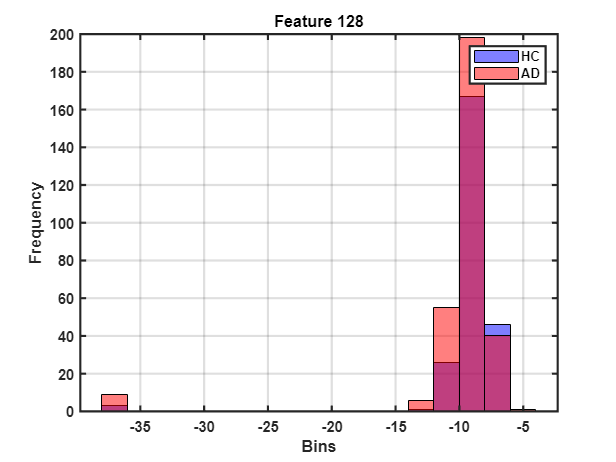

my_hist(128,feat_mx_log)

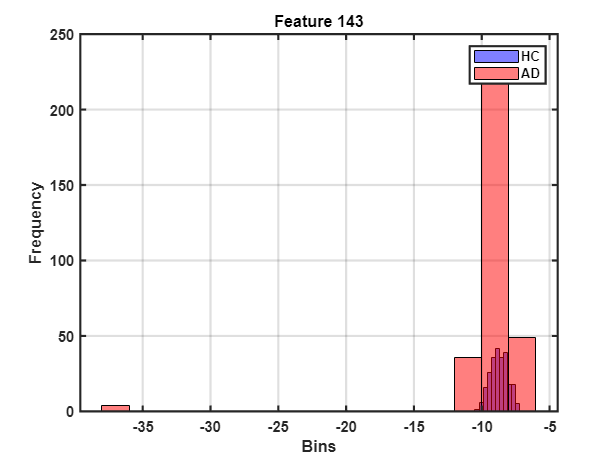

my_hist(143,feat_mx_log)

# KS Test (Log-transformed features)

num_hc = 243;

out_mx = NaN(size(feat_mx_log,2),4);
out_mx(:,4) = find(~zidx)';
for i=1:size(feat_mx_log,2)
    [out_mx(i,1),out_mx(i,2),out_mx(i,3)] = kstest2(feat_mx_log(1:num_hc,i),feat_mx_log(num_hc+1:end,i), ...
        'Alpha',0.05,'Tail','unequal');
end

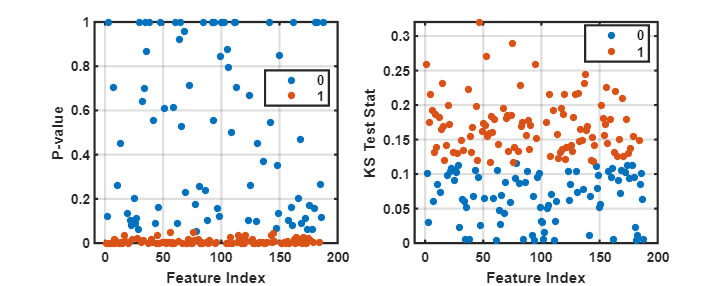

g = categorical(out_mx(:,1));
cidx = 1:size(feat_mx,2);

f = figure('Color','w','Position',[0,0,980,385]);
subplot(1,2,1)
gscatter(cidx,out_mx(:,2),g)
grid on
xlabel("Feature Index")
ylabel("P-value")
set(gca,'FontWeight','bold','LineWidth',1.5)

subplot(1,2,2)
gscatter(cidx,out_mx(:,3),g)
grid on
xlabel("Feature Index")
ylabel("KS Test Stat")
set(gca,'FontWeight','bold','LineWidth',1.5)

# Custom functions

function my_hist(i,feat_mx)
    num_hc = 243;
    histogram(feat_mx(1:num_hc,i),'FaceColor','b','FaceAlpha',0.5)
    hold on
    histogram(feat_mx(num_hc+1:end,i),'FaceColor','r','FaceAlpha',0.5)
    hold off
    grid on
    legend(["HC","AD"])
    title(strcat("Feature ",num2str(i)));
    xlabel("Bins")
    ylabel("Frequency")
    set(gca,'FontWeight','bold','LineWidth',1.5)
end